data = csvread('C:\Users\Devangi Chaudhary\Desktop\Flam R&D\xy_data.csv', 1, 0);  % Skip first row if it's headers
x = data(:,1);
y = data(:,2);

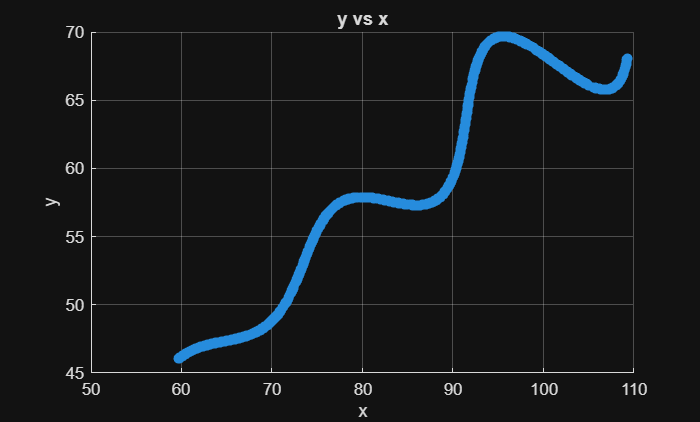

t = linspace(6, 60, 1500);

figure;
scatter(x, y, 'filled');
xlabel('x');
ylabel('y');
title('y vs x');
grid on;

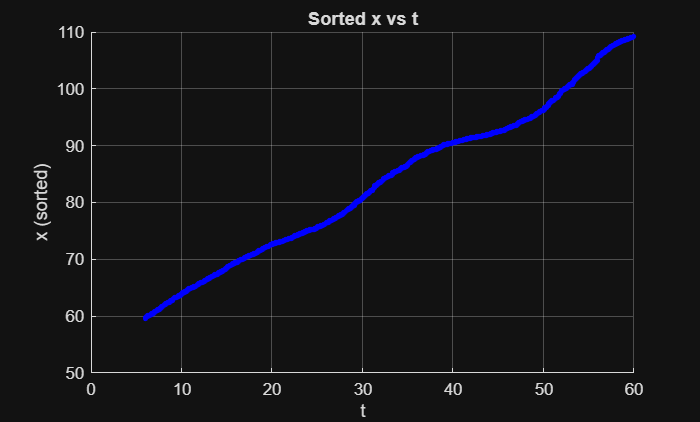

% --- Sort x and get corresponding y values
[x_sorted, idx] = sort(x);
y_sorted = y(idx);  % reorder y according to sorted x

% --- Plot sorted x vs t
figure;
scatter(t, x_sorted, 10, 'b', 'filled');
xlabel('t');
ylabel('x (sorted)');
title('Sorted x vs t');
grid on;

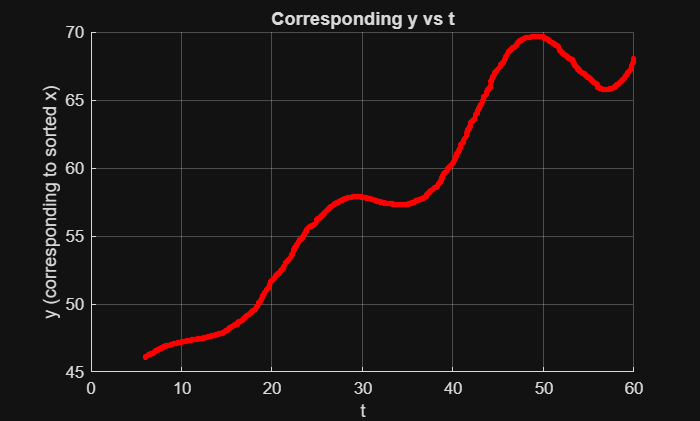


% --- Plot corresponding y vs t
figure;
scatter(t, y_sorted, 10, 'r', 'filled');
xlabel('t');
ylabel('y (corresponding to sorted x)');
title('Corresponding y vs t');
grid on;